% Author : Avishka Sandeepa
% Last Update : 29/08/2021

output = calcMyFilterSpecs(5, 6, 4); % call the function to get values for the given index

output = 	1.0e+03 *

    0.0001    0.0510    0.7000    1.1000    0.5500    1.2000    3.2000


% initialize the values 

Ws = output(7);   % set sample frequency value
T=2*pi/Ws;   % set the sampling period
delta_p = (10^(0.05*output(1)) - 1)/(10^(0.05*output(1)) + 1); % determine delta p value using Ap
delta_a = (10^((-0.05)*output(2))); % determine delta a value using Aa
delta = min(delta_a, delta_p); % find delta value
Actual_Aa = (-20)*log10(delta); % finding actual stopband attenuation
Bt = min((output(3) - output(5)), (output(6) - output(4)));   % create transition width
Wc1 = output(3) - Bt/2; % define the cutoff frequencies
Wc2 = output(4) + Bt/2;
valAlfa = getAlfa(Actual_Aa); % call the function to get value alpha
valD = getD(Actual_Aa);  % call the function to get value D



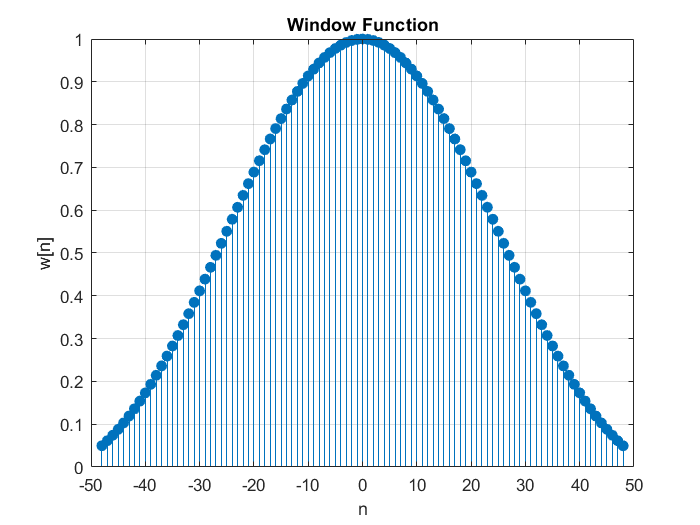

calcN = ceil((output(7)*valD)/Bt + 1); % calculate current N value and round it to the nearest integer
finalN = calcN + 1 - rem(calcN, 2); % get the correct N value

M = finalN - 1;
tau = M/2;
range1_n = -tau: 1: tau;   % define range of n value

valBeta = valAlfa*(1 - ((2*range1_n)/M).^2).^0.5; % Determine beta value
i0_alpha = bessel(valAlfa); % call the bessel function to fing window
i0_beta = bessel(valBeta);

win = i0_beta/i0_alpha; % find the window function for specified n values


stem(range1_n, win, "fill")
%ylim([0 1])
grid on;
xlabel("n");
ylabel("w[n]");
title("Window Function")

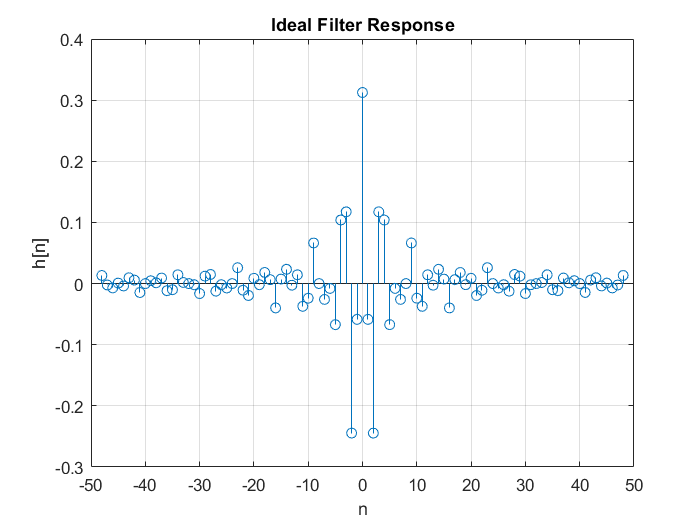


impulse_response = hnT(range1_n,Wc1,Wc2,Ws,T);  %create impulse response function for ideal filter
stem(range1_n, impulse_response)
xlabel("n"); ylabel("h[n]");
grid on
title ("Ideal Filter Response");

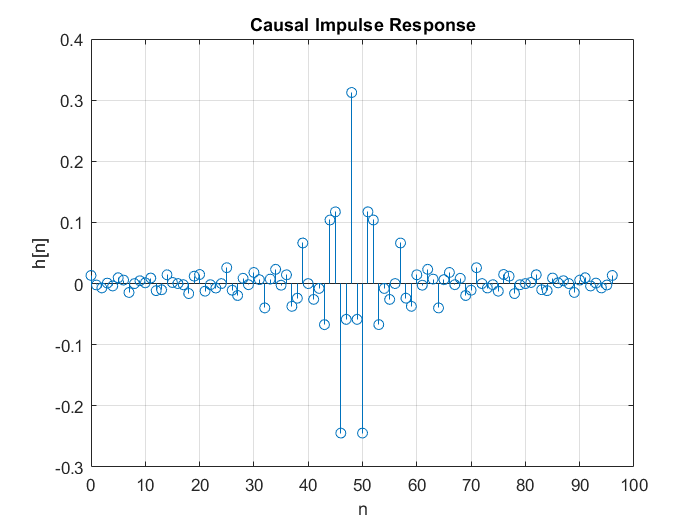

range2_n = 0:1:M;
stem(range2_n, impulse_response);  %causal response
xlabel("n"); ylabel("h[n]");
title("Causal Impulse Response");


grid on;

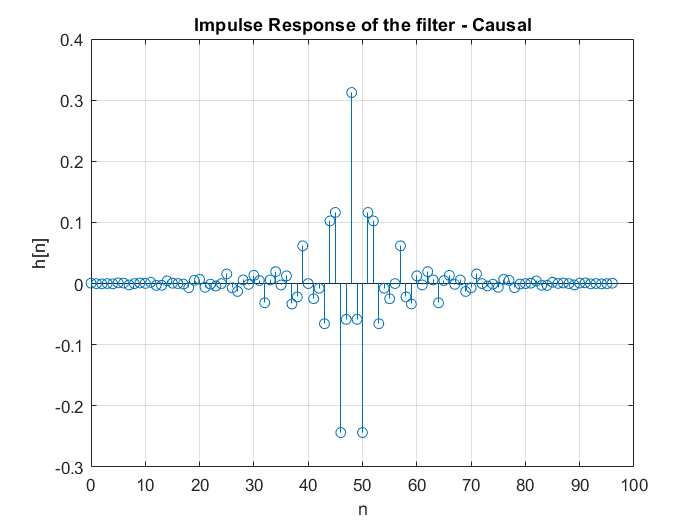

imp = impulse_response.*win; % Determine the impulse response of the filter - with causal condition
stem(range2_n, imp);
title("Impulse Response of the filter - Causal");
xlabel("n"); ylabel("h[n]")
grid on;

# `Functions`

function [valAlfa] = getAlfa(Attenuation) % choose parameter alfa (this will be calculated according to the theories of A. Antoniou's digital signal processing section 9.3 , 9.4

    if Attenuation <= 21
        valAlfa = 0;
    else
        if Attenuation > 50
            valAlfa = 0.1102*(Attenuation - 8.7);
        else
            valAlfa = 0.5842*(Attenuation - 21)^0.4 + 0.07886*(Attenuation-21);
        end
    end

end

%------------------------ choose parameter D as follows -----------------------------------------

function [valD] = getD(Attenuation)

    if Attenuation <= 21
        valD = 0.9222;
    else
        valD = (Attenuation - 7.95)/(14.36);
    end

end

%-------------------------------------- window function ----------------------------------------------   

function [i0_x] = bessel(x)
    i0_x = 1;
    for k = 1: 10
        i0_x = i0_x + (((x/2).^k)*(1/factorial(k))).^2;
    end

end

%--------------------------------- ideal filter function ---------------------------------------

function [impulse_response] = hnT(n,Wc1,Wc2,Ws,T) 
impulse_response=zeros(size(n));
   for c1 = 1:length(n)
       if n(c1)==0
           impulse_response(c1)=2*(Wc2-Wc1)/Ws;
       else
           impulse_response(c1)=(sin(n(c1)*Wc2*T)-sin(Wc1*n(c1)*T))/(n(c1)*pi);
       end
   end

end










## **Function for take values the last integers of Index Number **

function output= calcMyFilterSpecs(A, B, C)
    Ap = 0.03 + (0.01 * A); % Maximum passband ripple
    Aa = 45+B; % Minimum stopband attenuation
    Wp1 = (C * 100) + 300; % Lower passband edge
    Wp2 = (C * 100) + 700; % Upper passband edge
    Wa1 = (C * 100) + 150; % Lower stopband edge
    Wa2 = (C * 100) + 800; % Upper stopband edge
    Ws =  2*((C * 100) + 1200); % Sampling frequency

output = [Ap, Aa, Wp1, Wp2, Wa1, Wa2, Ws]
end

% this function helps to determine filter specified parameters when give three digits as an input.
% three digits are the last three digits of the university ID number